## **MATH803 Project Part A - Mannat Ahuja 22173443**

**Q1. Main characteristics of the data**

We take a look at the descriptive statistics of the data. Datetime column is represented by 'D' and hourly temperatures in Auckland are represented by 'T'. 

Upon checking the descriptive statistics, we find that the median hourly temperature for Auckland from 1 to 30 January is 21 degree Celsius, with the minimum value of the temperatures going as low as 13.8 degree Celsius, and the maximum value going as high as 28. The standard deviation of the hourly temperatures is 2.9129.

After plotting dateime on the x-axis and the temperatures on the y-axis, we find that every day, the temperatures reach a maximum during the day, and then fall towards a minimum value during the night, before it starts rising again. 

The histogram provides us some insights regarding the distribution of the data. According to the graph, the data seems to be bell-shaped, or normally distributed. 

summary(AKLJan2024Temp)

Variables:

    Datetime: 720×1 datetime

        Values:

            Min       2024-01-01T00:00:00
            Median    2024-01-15T23:30:00
            Max       2024-01-30T23:00:00

    Temperature: 720×1 double

        Values:

            Min         13.8  
            Median        21  
            Max           28  

    Hour: 720×1 double

        Values:

            Min            1  
            Median     360.5  
            Max          720  




D = AKLJan2024Temp.Datetime;
T = AKLJan2024Temp.Temperature;
hours = AKLJan2024Temp.Hour;

% Calculate standard deviation
std_dev = std(T);

disp(['Standard deviation: ', num2str(std_dev)]);

Standard deviation: 2.9129


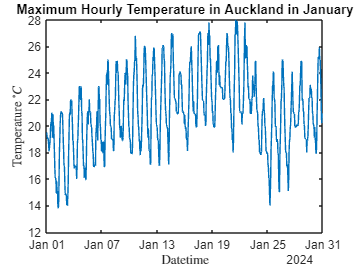


%Plotting the hourly temperatures
figure
clf
plot(D,T)
xlabel('Datetime','Interpreter','latex')
ylabel('Temperature $^\circ C$','Interpreter','latex')
title('Maximum Hourly Temperature in Auckland in January')


%Histogram to check distribution
nbins = 12;
figure
clf
h = histogram(T,nbins)

h =   Histogram with properties:

             Data: [720×1 double]
           Values: [7 13 21 83 86 95 160 94 53 66 36 6]
          NumBins: 12
         BinEdges: [13 14.3000 15.6000 16.9000 18.2000 19.5000 20.8000 22.1000 23.4000 24.7000 26 27.3000 28.6000]
         BinWidth: 1.3000
        BinLimits: [13 28.6000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


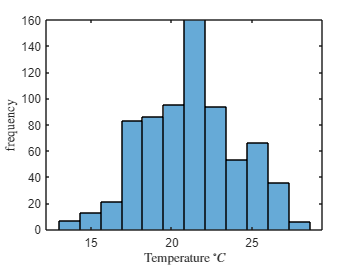

xlabel('Temperature $^\circ C$','Interpreter','latex')
ylabel('frequency','Interpreter','latex')

**Q2. Trends in the data**

To look for trends in the data, we have first used simple moving averages to smoothen it out. We have used Centre, Past and Future Moving Averages with a window size of 24. The centre moving averages provide a balanced view of the past and the future trends, whilst also minimising lags. The past moving averages are basedon the historical trends in the data, but may cause lags.The future moving averages provide the future data points, so we can see where it is headed, and forcast accordingly, but may be less reliable. 

Since we are focusing on predicting the future values of temperature in this case specifically, centre and future moving averages may be more useful.

We have also used linear and polynomial regression models for the analysis of the time-series data. Overall, linear model does not provide a good fit for the data (R-squared = 0.1534), but as we move up the order of polynomial models, the fit gets increasingly better. An Exponential Model may not be a suitable choice for this data because we wish to take a look at the short-term trends in the temperature. Moreover, the temperature does not exhibit a pattern of exponential growth or exponential decrease.

We are particularly interested in the order 5 polynomial model, which seems to provide a good fit for the data (R-squared is 0.7763 but adjusted-R-squared is 0.7297, which is the highest).About 77.63% of the variability in temperature is explained by this model.

**Centre, Past and Future Moving Averages**

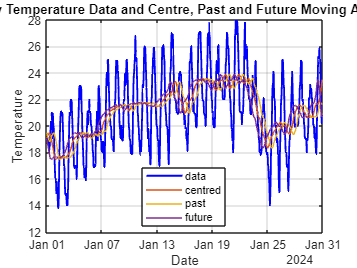

windowSize = 24;

% Plot hourly temperature data
figure;
clf
plot(D, T, 'b-', 'LineWidth', 1.5);
hold on;

M_centred_24=movmean(T,24);
plot(D, M_centred_24)
hold on;
M_past_24=movmean(T,[23,0]);
plot(D, M_past_24)
hold on;
M_future_24=movmean(T,[0,23]);
plot(D, M_future_24)
legend('data','centred','past','future','Location','best')

% Add labels and legend
xlabel('Date');
ylabel('Temperature');
title('Hourly Temperature Data and Centre, Past and Future Moving Averages');

% Set grid
grid on;

**Linear Regression**

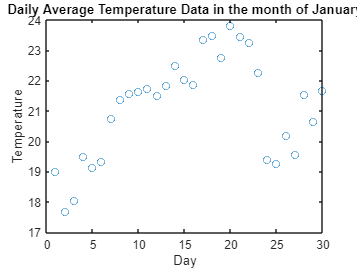

dt = datenum(D);
dates = reshape((1:30), 1, 30); %Representing the 30 days in January (starting from 1 representing 1 January 2024 and so on)
daily_average_temperatures = accumarray(day(D), T, [], @mean); %Taking the mean of hourly temperatures would be easier to visualise
clf
figure
plot(dates, daily_average_temperatures, 'o')
xlabel('Day');
ylabel('Temperature');
title('Daily Average Temperature Data in the month of January');

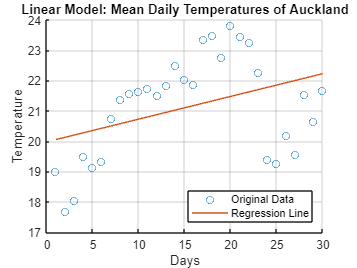


%Linear Regression
X = [ones(1, length(dates)); dates];
b1 = X'\daily_average_temperatures;
yCalc1 = (X'*b1)';

%Plotting the original data and the linear regression model
scatter(dates,daily_average_temperatures)
hold on
plot(dates,yCalc1)
xlabel('Days')
ylabel('Temperature')
title('Linear Model: Mean Daily Temperatures of Auckland')
grid on
legend('Original Data','Regression Line','Location','southeast')


n = 30; 
% R-Squared
Rsq2 = 1 - sum((daily_average_temperatures - yCalc1').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2 = 0.1534


% Adjusted R-Squared
Ad_Rsq2 = 1 - (1-Rsq2)*(n-1)/(n-1-1)

Ad_Rsq2 = 0.1231

** Polynomial Regression models**

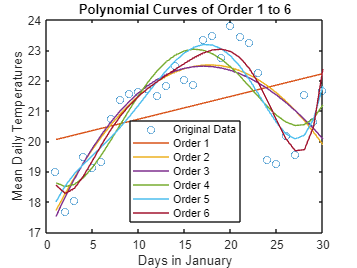

%Calculating the coefficients
coef1 = polyfit(dates,daily_average_temperatures,1); %Order 1
coef2 = polyfit(dates,daily_average_temperatures,2); %Order 2
coef3 = polyfit(dates,daily_average_temperatures,3); %Order 3
coef4 = polyfit(dates,daily_average_temperatures,4); %Order 4
coef5 = polyfit(dates,daily_average_temperatures,5); %Order 5
coef6 = polyfit(dates,daily_average_temperatures,6); %Order 6

pred1 = polyval(coef1,dates);
pred2 = polyval(coef2,dates);
pred3 = polyval(coef3,dates);
pred4 = polyval(coef4,dates);
pred5 = polyval(coef5,dates);
pred6 = polyval(coef6,dates);

%Plotting the models
clf
plot(dates,daily_average_temperatures,'o')
hold on;
plot(dates,pred1);
plot(dates,pred2);
plot(dates,pred3);
plot(dates,pred4);
plot(dates,pred5);
plot(dates,pred6);

xlabel('Days in January')
ylabel('Mean Daily Temperatures')
title('Polynomial Curves of Order 1 to 6')
legend('Original Data','Order 1','Order 2', 'Order 3', 'Order 4', 'Order 5', 'Order 6', 'Location','south')
hold off


% R-Squared for the models
Rsq2_poly1 = 1 - sum((daily_average_temperatures - pred1').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly1 = 0.1534

Rsq2_poly2 = 1 - sum((daily_average_temperatures - pred2').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly2 = 0.6407

Rsq2_poly3 = 1 - sum((daily_average_temperatures - pred3').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly3 = 0.6436

Rsq2_poly4 = 1 - sum((daily_average_temperatures - pred4').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly4 = 0.7406

Rsq2_poly5 = 1 - sum((daily_average_temperatures - pred5').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly5 = 0.7763

Rsq2_poly6 = 1 - sum((daily_average_temperatures - pred6').^2)/sum((daily_average_temperatures - mean(daily_average_temperatures)).^2)

Rsq2_poly6 = 0.8116

% Adjusted R-Squared
Ad_Rsq2_poly1 = 1 - (1-Rsq2_poly1)*(n-1)/(n-1-1)

Ad_Rsq2_poly1 = 0.1231

Ad_Rsq2_poly2 = 1 - (1-Rsq2_poly2)*(n-1)/(n-2-1)

Ad_Rsq2_poly2 = 0.6141

Ad_Rsq2_poly3 = 1 - (1-Rsq2_poly3)*(n-1)/(n-3-1)

Ad_Rsq2_poly3 = 0.6025

Ad_Rsq2_poly4 = 1 - (1-Rsq2_poly4)*(n-1)/(n-4-1)

Ad_Rsq2_poly4 = 0.6991

Ad_Rsq2_poly5 = 1 - (1-Rsq2_poly5)*(n-1)/(n-5-1)

Ad_Rsq2_poly5 = 0.7297

Ad_Rsq2_poly6 = 1 - (1-Rsq2_poly5)*(n-1)/(n-6-1)

Ad_Rsq2_poly6 = 0.7179

**Q3. Predicting Temperature on 31 January 2024 using Extrapolation**

We are required to predict the value of daily average temperatures for 31 January 2024. For this, we will plot the extrapolation curves. We start by extending the vectors 'dates', and then we plot the models. As calculated above, we converted the hourly temperatures into daily average temperatures from 1 January to 30 January. The x-axis represents the days, with '1' representing the first day of January, and so on. The y-axis represents the average daily temperatures for every day of January in Auckland. According to our calculations above, as we move up the order of the polynomial, it provides us a better fit, with Order 5 being the best fit out of all of them, since it has the highest Adjusted R-Squared. 

The average temperature of Auckland on 31 January 2024, as estimated by the polynomial model of order 1 is 22.298 degrees Celsius, as shown by the red curve. Polynomial curve of order 1 does not provide a very good fit (R-square = 0.1534 and Adj-R-Square = 0.1231). We will therefore look into models of higher orders. 

The average temperature of Auckland on 31 January 2024, as estimated by the polynomial of order 2 is 19.4403 degrees Celsius, for order 3 is 19.7297,  for order 4 is 21.8931, for order 5 is 23.6091, and for order 6 is 25.8833

Like said before, order 5 provides a good fit for the data, so the estimate for the mean daily temperature on 31 January provided by the model is perhaps the best out of the ones we have plotted. 

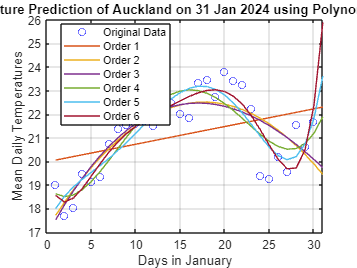

%Extrapolation to calculate the mean temperature for 31 January 2024.
dates_ex = 1:1:31; 
p1 = polyfit(dates, daily_average_temperatures, 1);
y_extrapolated_poly1 = polyval(p1, dates_ex);

p2 = polyfit(dates, daily_average_temperatures, 2);
y_extrapolated_poly2 = polyval(p2, dates_ex);

p3 = polyfit(dates, daily_average_temperatures, 3);
y_extrapolated_poly3 = polyval(p3, dates_ex);

p4 = polyfit(dates, daily_average_temperatures, 4);
y_extrapolated_poly4 = polyval(p4, dates_ex);

p5 = polyfit(dates, daily_average_temperatures, 5);
y_extrapolated_poly5 = polyval(p5, dates_ex);

p6 = polyfit(dates, daily_average_temperatures, 6);
y_extrapolated_poly6 = polyval(p6, dates_ex);

%Plotting 
figure
clf
plot(dates, daily_average_temperatures, 'bo', 'DisplayName', 'Data Points');
hold on

plot(dates_ex, y_extrapolated_poly1);
plot(dates_ex, y_extrapolated_poly2);
plot(dates_ex, y_extrapolated_poly3);
plot(dates_ex, y_extrapolated_poly4);
plot(dates_ex, y_extrapolated_poly5);
plot(dates_ex, y_extrapolated_poly6);

legend('Original Data','Order 1','Order 2','Order 3','Order 4','Order 5','Order 6','Location','best');
xlabel('Days in January')
ylabel('Mean Daily Temperatures')
title('Temperature Prediction of Auckland on 31 Jan 2024 using Polynomial Model')
grid on


%Estimated values based on different models
akl_temp_31Jan_poly1 = polyval(p1, 31)

akl_temp_31Jan_poly1 = 22.2987

akl_temp_31Jan_poly2 = polyval(p2, 31)

akl_temp_31Jan_poly2 = 19.4403

akl_temp_31Jan_poly3 = polyval(p3, 31)

akl_temp_31Jan_poly3 = 19.7297

akl_temp_31Jan_poly4 = polyval(p4, 31)

akl_temp_31Jan_poly4 = 21.8931

akl_temp_31Jan_poly5 = polyval(p5, 31)

akl_temp_31Jan_poly5 = 23.6091

akl_temp_31Jan_poly6 = polyval(p6, 31)

akl_temp_31Jan_poly6 = 25.8833

**Q4. Periodicity via Fourier Transformation and Autocorrelation**

As we can see from the plot above, the temperatures do have a periodicity, wherein they reach their maximum during the day, and their minimum during the night, and so on. Fourier transformation helps us identify frequency transformations in the data. Using the fft function, we will take the fourier transformation of the Hourly Temperature data minus the mean. The output contains the mirror image of complex Fourier coefficients about the real axis. 

It is to be kept in mind that Fourier coefficients are not very easy to interpret, and it would be more meaningful to square their magnitudes. We only need to compute the power of one half of the coefficients. We will plot the power spectrum as a function of frequency, measured in cycles per day.

The plot suggests that maximum temperatures occur less frequently than once per day. For a view of the cyclical activity that is easier to interpret, we plot power as a function of period, measured in days per cycle.  The plot reveals that temperatures peak about once every 23 hours.

We have also plotted the autocorrelation plots, first for 20 and 24 lags (which do not provide us much information) and then for 719 lags (720 hours in a month, minus 1) which suggests that overall, the autocorrelation function is decreasing and is approaching zero as the number of lags increases.

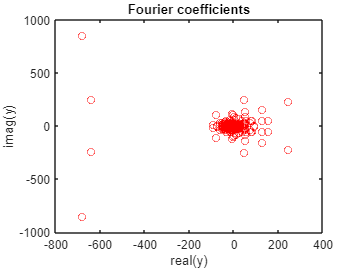

D = AKLJan2024Temp.Datetime; %Using the original data for the hourly temperatures
T = AKLJan2024Temp.Temperature;

figure
clf
T_0=T-mean(T); % to make sure the mean is zero, 
% this removes the large DC component otherwise seen at zero Hz in the fft
y = fft(T_0);
plot(y,'ro')
xlabel('real(y)')
ylabel('imag(y)')
title('Fourier coefficients')

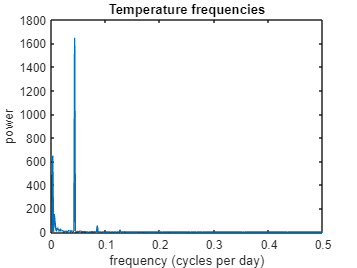


%Plotting temperature frequencies
figure
clf
n = length(y); % Number of data points used for the FFT
power = abs(y(1:floor(n/2))).^2/n; % power of first half of transform data
nyquist=1/2; % measured once per day, half of this, this is the maximum frequency we can detect
freq = (1:floor(n/2))/(n/2)*nyquist;    % equally spaced frequency grid
plot(freq,power)
xlabel("frequency (cycles per day)")
ylabel("power")
title("Temperature frequencies")

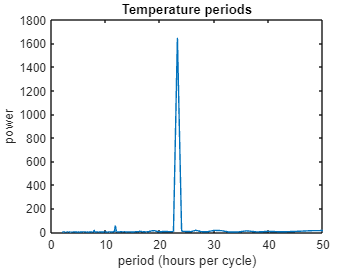


%Plotting temperature periods
figure
clf
period = 1./freq;
plot(period,power);
xlim([0 50]); % later to zoom in on max power
xlabel("period (hours per cycle)")
ylabel("power")
title("Temperature periods")

index2=find(power==max(power));
period_temp=period(index2)

period_temp = 23.2258

**Autocorrelation**

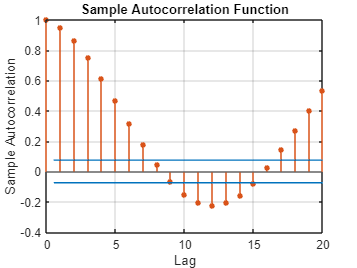

autocorr(T) % draws a graph

[acf,lags,bounds]=autocorr(T)

acf =     1.0000
    0.9520
    0.8653
    0.7499
    0.6155
    0.4691
    0.3182
    0.1752
    0.0424
   -0.0696


lags =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


bounds =     0.0745
   -0.0745


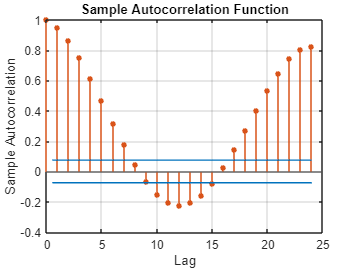


NumLags=24; %for 24 hours in a day
figure
clf
autocorr(T,NumLags=24)

**Plotting for the whole month**

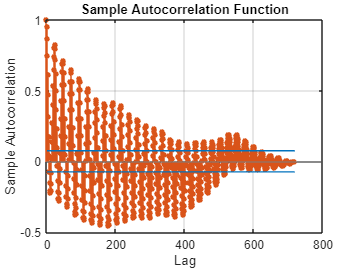

NumLags=719; %for the whole month (720-1)
figure
clf
autocorr(T,NumLags=719)